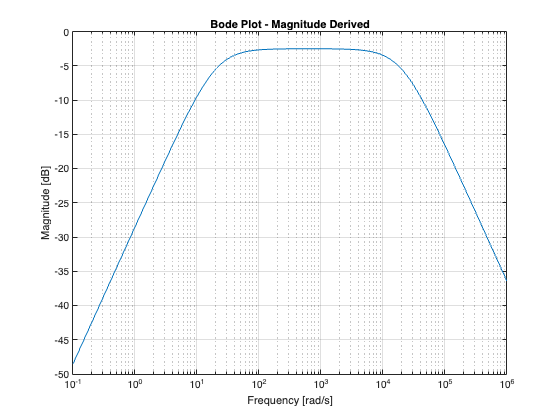

clear; clc; close all;

Ri = 2.5e3;
R1 = 10e3;
R2 = 7.5e3;
C1 = 10e-6;
C2 = (80/3)*10^-9;

s = 1i * logspace(-1, 6, 10000);

a = C1*C2*R2*R1*Ri;
b = (C2*R2*Ri) + (C1*R1*R2) + (C1*R1*Ri) + (C2*R2*R1);
c = R2 + R1 + Ri;

coeff = [a, b, c];

w = roots(coeff);

w1 = w(1);
w2 = w(2);

K = C1*R1*R2;

denominator_derived = a .* s.^2 + b .* s + c;

H_derived = K .* s ./ denominator_derived;

mag_derived = 20*log10(abs(H_derived));
phase_derived = angle(H_derived) * (180/pi);

figure;
semilogx(abs(imag(s)), mag_derived);
grid on;
title('Bode Plot - Magnitude Derived');
xlabel('Frequency [rad/s]');
ylabel('Magnitude [dB]');

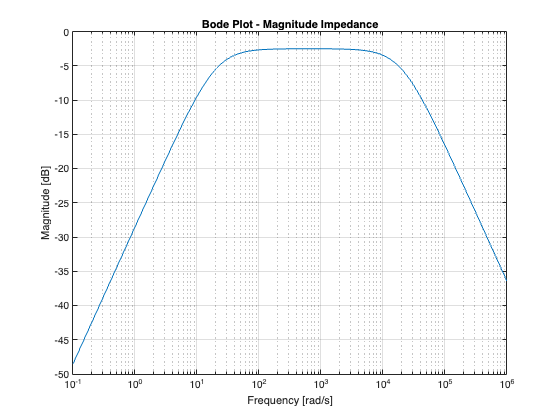

% Impedance-based H(s) calculation
Z_C1 = 1 ./ (s .* C1);
Z_C2 = 1 ./ (s .* C2);
Z_eq = (Z_C2 .* R2) ./ (Z_C2 + R2);
Z_th = Ri + ((R1 .* Z_C1) ./ (R1 + Z_C1));

Vth_over_Vin = R1 ./ (R1 + Z_C1);

H_impedance = Vth_over_Vin .* (Z_eq ./ (Z_eq + Z_th));

mag_impedance = 20*log10(abs(H_impedance));
phase_impedance = angle(H_impedance) * (180/pi);

figure;
semilogx(abs(imag(s)), mag_impedance);
grid on;
title('Bode Plot - Magnitude Impedance');
xlabel('Frequency [rad/s]');
ylabel('Magnitude [dB]');